#### Example: A signal sampled at 1000 Hz is composed of two sinusoids of frequencies 100 Hz and 50 Hz. The Signal is sent to an LTI system. Design the system such that it will reject the 50 Hz component. 

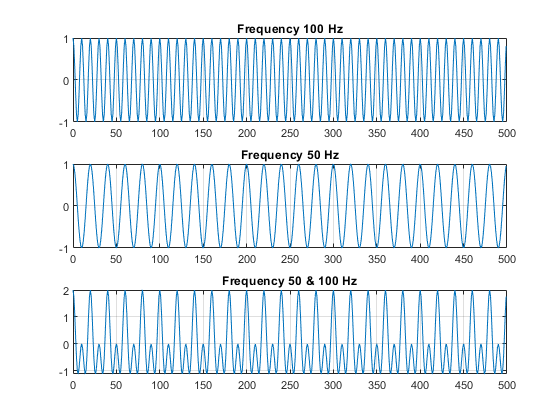

clc; close all, clear all;
Fs=1000; 
T=1/Fs;
F1=100; 
F2=50;
n=0:1:Fs/2-1;
s1=cos(2*pi*F1*n*T); 
s2=cos(2*pi*F2*n*T);
s=s1+s2;
h=[1 -1.9021130326 1];
N=Fs/2;
df=1/(N*T);
f=n*df;
FFT100=abs(fft(s1,N)); % Fourier transform of s1
FFT50=abs(fft(s2,N)); %Fourier transform of s2
FFT150=abs(fft(s,N)); % Fourier transform of s
FFTh=abs(fft(h,N)); % Fourier transform of h
FFTy=FFT150.*FFTh; % Multiplication
y=ifft(FFTy,N); % Inverse Fourier transform to get time-domain sequence

figure; 
subplot(3,1,1) %% Time-domain s1
plot(n,s1)
title('Frequency 100 Hz')
grid on
subplot(3,1,2); %%Time-domain s2
plot(n,s2)
title('Frequency 50 Hz')
grid on
subplot(3,1,3); %%Time-domain s
plot(n,s)
title('Frequency 50 & 100 Hz')
grid on

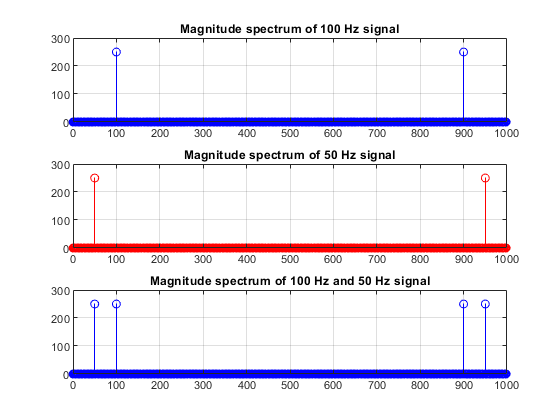

figure;
subplot(3,1,1); % Frequency-domain s1
stem(f,FFT100,'-b')
title('Magnitude spectrum of 100 Hz signal')
grid on
subplot(3,1,2); % Frequency-domain s2
stem(f,FFT50,'-r')
title('Magnitude spectrum of 50 Hz signal')
grid on
subplot(3,1,3); % Frequency-domain s
stem(f,FFT150,'-b')
title('Magnitude spectrum of 100 Hz and 50 Hz signal')
grid on

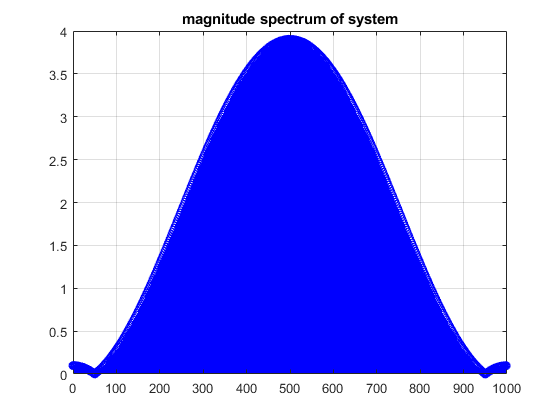

figure; % Frequency-domain h
stem(f,FFTh,'-b')
title('magnitude spectrum of system')
grid on

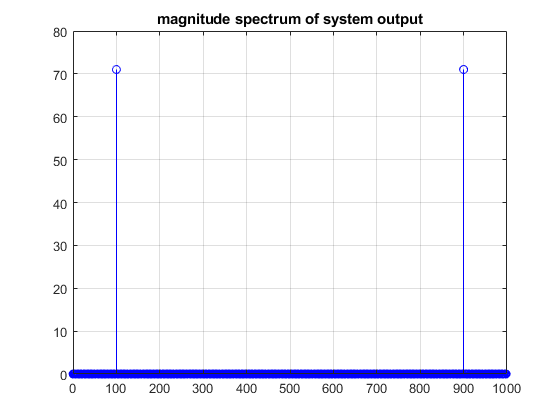

figure;
stem(f,FFTy,'-b'); % Frequency-domain y
title('magnitude spectrum of system output')
grid on

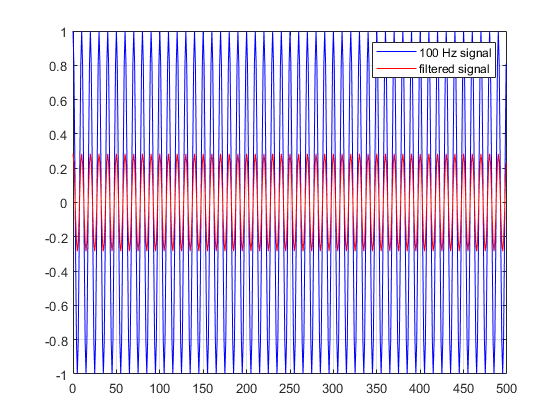

figure; % Frequency-domain s1 & time-domain y
plot(n,s1,'-b',n,y,'-r')
grid on
legend('100 Hz signal','filtered signal')